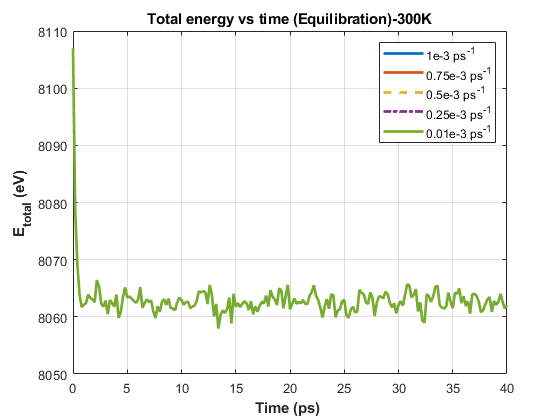

%%%%% ..a......
clc
clear all
close all

%%% fig 1:  Equilibration--time,etotal,pe,temp,pzz
%%%%% fig2:  deformation---time,etotal,pe,temp,strain,pzz


%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.
CNT200Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.1.Equi.txt','r');
CNT200Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.1.Deform.txt','r');
CNT200Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.75.Equi.txt','r');
CNT200Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.75.Deform.txt','r');
CNT200Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.5.Equi.txt','r');
CNT200Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.5.Deform.txt','r');
CNT200Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.25.Equi.txt','r');
CNT200Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.25.Deform.txt','r');
CNT200Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.01.Equi.txt','r');
CNT200Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.300K.01.Deform.txt','r');

EquCNT2001 = cell2mat(textscan(CNT200Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT2001 =cell2mat(textscan(CNT200Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT20075 = cell2mat(textscan(CNT200Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT20075 =cell2mat(textscan(CNT200Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT2005 = cell2mat(textscan(CNT200Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT2005 =cell2mat(textscan(CNT200Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT20025 = cell2mat(textscan(CNT200Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT20025 =cell2mat(textscan(CNT200Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT20001 = cell2mat(textscan(CNT200Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT20001 =cell2mat(textscan(CNT200Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT200Equ1);
fclose(CNT200Def1);
fclose(CNT200Equ75);
fclose(CNT200Def75);
fclose(CNT200Equ5);
fclose(CNT200Def5);
fclose(CNT200Equ25);
fclose(CNT200Def25);
fclose(CNT200Equ01);
fclose(CNT200Def01);

figure(1)  %%% equilibtration...
plot(EquCNT2001(:,1),EquCNT2001(:,2),"LineWidth",2); 
hold on
plot(EquCNT20075(:,1),EquCNT20075(:,2),"LineWidth",2); 
hold on
plot(EquCNT2005(:,1),EquCNT2005(:,2),'--',"LineWidth",2); 
hold on
plot(EquCNT20025(:,1),EquCNT20025(:,2),'-.',"LineWidth",2); 
hold on
plot(EquCNT20001(:,1),EquCNT20001(:,2),"LineWidth",2); 
title('Total energy vs time (Equilibration)-300K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','0.01e-3 ps^{-1}')
grid on
hold off

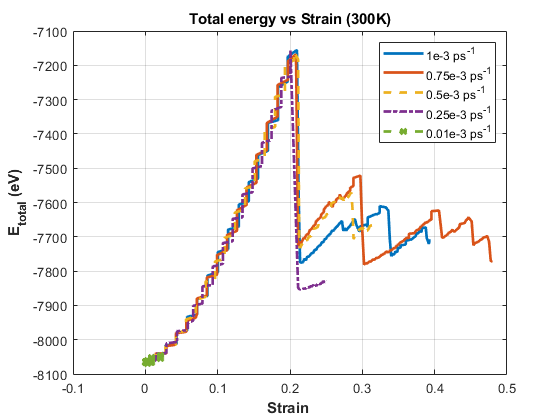


figure(2);   %deformation.........
plot(DefCNT2001(:,5),DefCNT2001(:,2),"LineWidth",2); 
hold on
plot(DefCNT20075(:,5),DefCNT20075(:,2),"LineWidth",2); 
hold on
plot(DefCNT2005(:,5),DefCNT2005(:,2),'--',"LineWidth",2); 
hold on
plot(DefCNT20025(:,5),DefCNT20025(:,2),'-.',"LineWidth",2); 
hold on
plot(DefCNT20001(:,5),DefCNT20001(:,2),'--x',"LineWidth",2); 
title('Total energy vs Strain (300K)')
xlabel('Strain ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','0.01e-3 ps^{-1}')
grid on

hold off

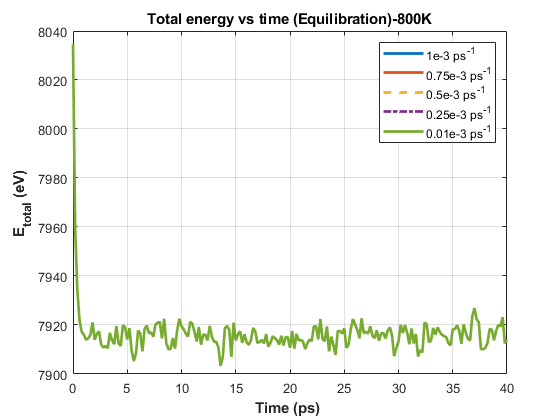



%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K
CNT200Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.1.Equi.txt','r');
CNT200Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.1.Deform.txt','r');
CNT200Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.75.Equi.txt','r');
CNT200Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.75.Deform.txt','r');
CNT200Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.5.Equi.txt','r');
CNT200Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.5.Deform.txt','r');
CNT200Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.25.Equi.txt','r');
CNT200Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.25.Deform.txt','r');
CNT200Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.01.Equi.txt','r');
CNT200Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.800K.01.Deform.txt','r');

EquCNT2001 = cell2mat(textscan(CNT200Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT2001 =cell2mat(textscan(CNT200Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT20075 = cell2mat(textscan(CNT200Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT20075 =cell2mat(textscan(CNT200Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT2005 = cell2mat(textscan(CNT200Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT2005 =cell2mat(textscan(CNT200Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT20025 = cell2mat(textscan(CNT200Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT20025 =cell2mat(textscan(CNT200Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT20001 = cell2mat(textscan(CNT200Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT20001 =cell2mat(textscan(CNT200Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT200Equ1);
fclose(CNT200Def1);
fclose(CNT200Equ75);
fclose(CNT200Def75);
fclose(CNT200Equ5);
fclose(CNT200Def5);
fclose(CNT200Equ25);
fclose(CNT200Def25);
fclose(CNT200Equ01);
fclose(CNT200Def01);

figure(3)  %%% equilibtration...stress vs time
plot(EquCNT2001(:,1),EquCNT2001(:,2),"LineWidth",2); 
hold on
plot(EquCNT20075(:,1),EquCNT20075(:,2),"LineWidth",2); 
hold on
plot(EquCNT2005(:,1),EquCNT2005(:,2),'--',"LineWidth",2); 
hold on
plot(EquCNT20025(:,1),EquCNT20025(:,2),'-.',"LineWidth",2); 
hold on
plot(EquCNT20001(:,1),EquCNT20001(:,2),"LineWidth",2); 
title('Total energy vs time (Equilibration)-800K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','0.01e-3 ps^{-1}')
grid on
hold off

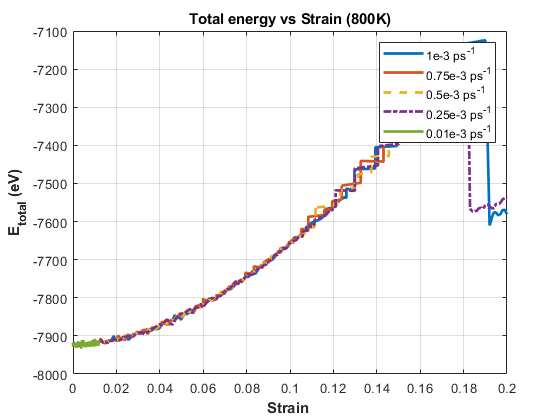


figure(4);   %deformation
plot(DefCNT2001(:,5),DefCNT2001(:,2),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT20075(:,5),DefCNT20075(:,2),"LineWidth",2);
hold on
plot(DefCNT2005(:,5),DefCNT2005(:,2),'--',"LineWidth",2);
hold on
plot(DefCNT20025(:,5),DefCNT20025(:,2),'-.',"LineWidth",2);
hold on
plot(DefCNT20001(:,5),DefCNT20001(:,2),"LineWidth",2);

title('Total energy vs Strain (800K)')
xlabel('Strain ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','0.01e-3 ps^{-1}')
grid on

hold off

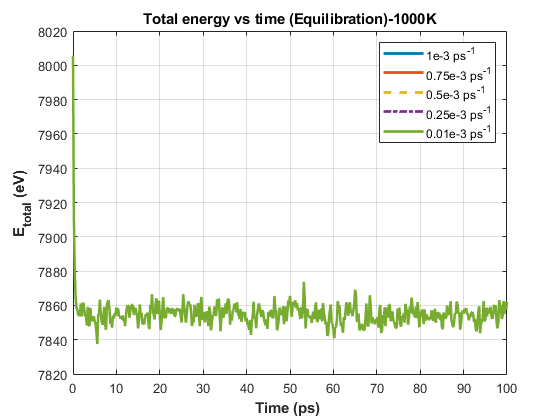




%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K
CNT200Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K.1.Equi.txt','r');
CNT200Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K.1.Deform.txt','r');
CNT200Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K.75.Equi.txt','r');
CNT200Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K.75.Deform.txt','r');
CNT200Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K.5.Equi.txt','r');
CNT200Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K.5.Deform.txt','r');
CNT200Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K.25.Equi.txt','r');
CNT200Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K.25.Deform.txt','r');
CNT200Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K.01.Equi.txt','r');
CNT200Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.1000K.01.Deform.txt','r');

EquCNT2001 = cell2mat(textscan(CNT200Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT2001 =cell2mat(textscan(CNT200Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT20075 = cell2mat(textscan(CNT200Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT20075 =cell2mat(textscan(CNT200Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT2005 = cell2mat(textscan(CNT200Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT2005 =cell2mat(textscan(CNT200Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT20025 = cell2mat(textscan(CNT200Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT20025 =cell2mat(textscan(CNT200Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT20001 = cell2mat(textscan(CNT200Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT20001 =cell2mat(textscan(CNT200Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT200Equ1);
fclose(CNT200Def1);
fclose(CNT200Equ75);
fclose(CNT200Def75);
fclose(CNT200Equ5);
fclose(CNT200Def5);
fclose(CNT200Equ25);
fclose(CNT200Def25);
fclose(CNT200Equ01);
fclose(CNT200Def01);

figure(5)  %%% equilibtration...stress vs time
plot(EquCNT2001(:,1),EquCNT2001(:,2),"LineWidth",2); 
hold on
plot(EquCNT20075(:,1),EquCNT20075(:,2),"LineWidth",2); 
hold on
plot(EquCNT2005(:,1),EquCNT2005(:,2),'--',"LineWidth",2); 
hold on
plot(EquCNT20025(:,1),EquCNT20025(:,2),'-.',"LineWidth",2); 
hold on
plot(EquCNT20001(:,1),EquCNT20001(:,2),"LineWidth",2); 
title('Total energy vs time (Equilibration)-1000K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','0.01e-3 ps^{-1}')
grid on
hold off

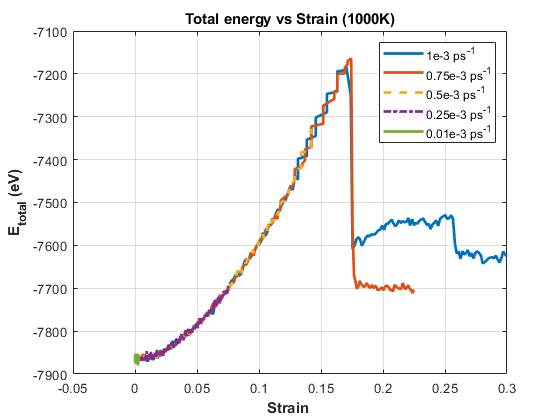


figure(6);   %deformation
plot(DefCNT2001(:,5),DefCNT2001(:,2),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT20075(:,5),DefCNT20075(:,2),"LineWidth",2);
hold on
plot(DefCNT2005(:,5),DefCNT2005(:,2),'--',"LineWidth",2); 
hold on
plot(DefCNT20025(:,5),DefCNT20025(:,2),'-.',"LineWidth",2); 
hold on
plot(DefCNT20001(:,5),DefCNT20001(:,2),"LineWidth",2);

title('Total energy vs Strain (1000K)')
xlabel('Strain ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','0.01e-3 ps^{-1}')
grid on

hold off

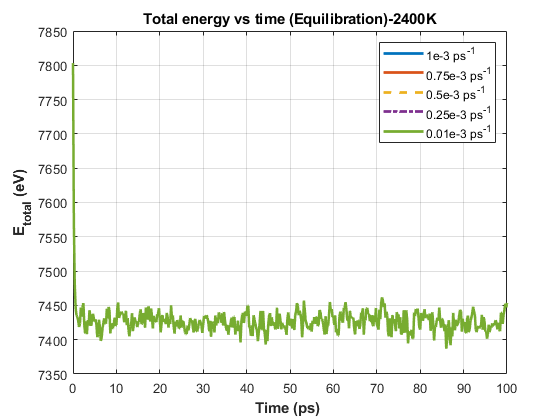




%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K
CNT200Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.1.Equi.txt','r');
CNT200Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.1.Deform.txt','r');
CNT200Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.75.Equi.txt','r');
CNT200Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.75.Deform.txt','r');
CNT200Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.5.Equi.txt','r');
CNT200Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.5.Deform.txt','r');
CNT200Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.25.Equi.txt','r');
CNT200Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.25.Deform.txt','r');
CNT200Equ01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.01.Equi.txt','r');
CNT200Def01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\CNT.20.0.60.2400K.01.Deform.txt','r');

EquCNT2001 = cell2mat(textscan(CNT200Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT2001 =cell2mat(textscan(CNT200Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT20075 = cell2mat(textscan(CNT200Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT20075 =cell2mat(textscan(CNT200Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT2005 = cell2mat(textscan(CNT200Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT2005 =cell2mat(textscan(CNT200Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT20025 = cell2mat(textscan(CNT200Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT20025 =cell2mat(textscan(CNT200Def25,'%f%f%f%f%f%f','headerlines',1));
EquCNT20001 = cell2mat(textscan(CNT200Equ01,'%f%f%f%f%f','headerlines',1));
DefCNT20001 =cell2mat(textscan(CNT200Def01,'%f%f%f%f%f%f','headerlines',1));


fclose(CNT200Equ1);
fclose(CNT200Def1);
fclose(CNT200Equ75);
fclose(CNT200Def75);
fclose(CNT200Equ5);
fclose(CNT200Def5);
fclose(CNT200Equ25);
fclose(CNT200Def25);
fclose(CNT200Equ01);
fclose(CNT200Def01);

figure(7)  %%% equilibtration...stress vs time
plot(EquCNT2001(:,1),EquCNT2001(:,2),"LineWidth",2); 
hold on
plot(EquCNT20075(:,1),EquCNT20075(:,2),"LineWidth",2); 
hold on
plot(EquCNT2005(:,1),EquCNT2005(:,2),'--',"LineWidth",2); 
hold on
plot(EquCNT20025(:,1),EquCNT20025(:,2),'-.',"LineWidth",2); 
hold on
plot(EquCNT20001(:,1),EquCNT20001(:,2),"LineWidth",2); 
title('Total energy vs time (Equilibration)-2400K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','0.01e-3 ps^{-1}')
grid on
hold off

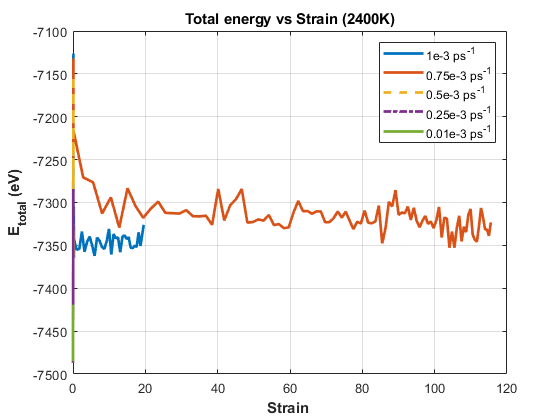


figure(8);   %deformation
plot(DefCNT2001(:,5),DefCNT2001(:,2),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT20075(:,5),DefCNT20075(:,2),"LineWidth",2);
hold on
plot(DefCNT2005(:,5),DefCNT2005(:,2),'--',"LineWidth",2); 
hold on
plot(DefCNT20025(:,5),DefCNT20025(:,2),'-.',"LineWidth",2); 
hold on
plot(DefCNT20001(:,5),DefCNT20001(:,2),"LineWidth",2);
title('Total energy vs Strain (2400K)')
xlabel('Strain ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','0.01e-3 ps^{-1}')
grid on

hold off